randn('state',100) % set the state of randn
T = 1; N = 500; dt = T/N;
dW = zeros(1,N); % preallocate arrays ...
W = zeros(1,N); % for efficiency

dW(1) = sqrt(dt)*randn; %first approximation outside the loop
W(1) = dW(1); % since W(0) = 0 is not allowed
for j = 2:N
    dW(j) = sqrt(dt)*randn; % general increment
    W(j) = W(j-1) + dW(j);
end
plot([0:dt:T],[0,W],'r-') % plot W against t

Error using plot
Vectors must be the same length.

xlabel('t','FontSize',16)
ylabel('W(t)','FontSize',16,'Rotation',0)
hold on

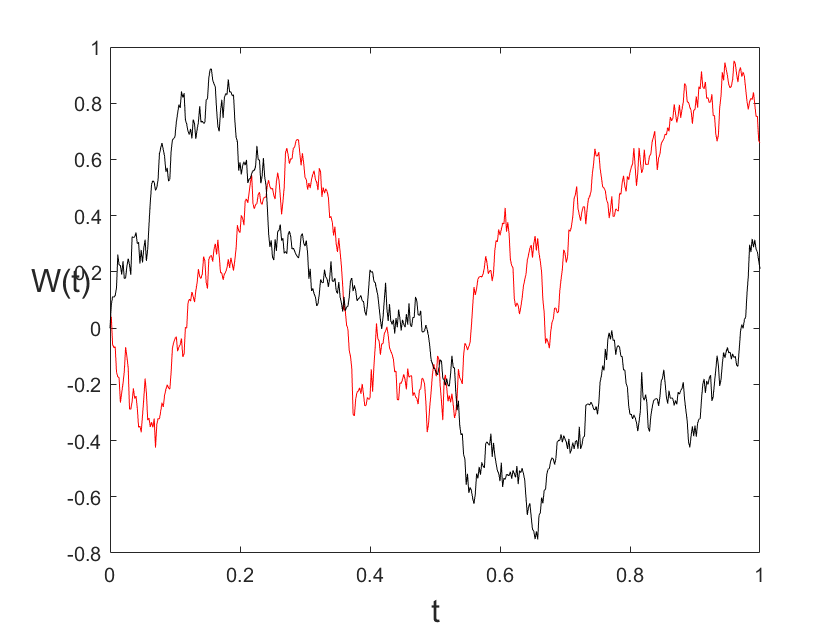

randn('state',200) % set the state of randn
T = 1; N = 500; dt = T/N;
dW = zeros(1,N); % preallocate arrays ...
W = zeros(1,N); % for efficiency

dW(1) = sqrt(dt)*randn; %first approximation outside the loop
W(1) = dW(1); % since W(O) = 0 is not allowed
for j = 2:N
    dW(j) = sqrt(dt)*randn; % general increment
    W(j) = W(j-1) + dW(j);
end
plot([0:dt:T],[0,W],'k-') % plot W against t
xlabel('t','FontSize',16)
ylabel('W(t)','FontSize',16,'Rotation',0)

length([0:dt:T])

ans = 501